# Predict cancer metabolism from histone markers

**Author**: Scott Campit

## Summary

This notebook trains regressors on global chromatin profiles from the Cancer Cell Line Encylopedia to predict metabolite and metabolite ratio levels. Other validation sets are also used from the trained CCLE models.

## Data Preprocessing

First, we'll read in the dataset, which consists of histone markers with single modifications, and metabolites that are involved in metabolic pathways related to histone acetylation and methylation.

clear all; 

GCPFilePath = '~/Data/Proteomics/CCLE/CCLE Global Chromatin Profiles.xlsx';
GCPSheet    = 'ACME'; 
GCP = readcell(GCPFilePath, ...
                "FileType", "spreadsheet", ...
                "Sheet", GCPSheet);
            
MetFilePath = '~/Data/Metabolomics/CCLE/ACME.csv';
MET = readcell(MetFilePath);
MET(:, 1) = [];

### Keep chromatin marker and metabolite identifiers

First get chromatin markers and metabolite identifiers.

% IDs
chromatin_markers = string(GCP(1, 2:end));
metabolites       = string(MET(1, 2:end));

### Get cell line intersection between datasets

Next, get the intersection between both datasets based on cancer cell lines.

% Map data based on intersection
[~, ia, ib] = intersect(string(GCP(:, 1)), string(MET(:, 1)));
GCP = GCP(ia, :);
MET = MET(ib, :);

### Remove unnecessary string identifiers

Finally, remove string identifiers from the dataset.

% Remove cell line identifiers
GCP(:, 1)  = [];
MET(:, 1) = [];

### Ensure all data types are double

Convert all data to the same datatype double.

% GCP datasets
GCP = string(GCP);
GCP = str2double(GCP);

% Metabolomics datasets
MET = string(MET);
MET = str2double(MET);

### Ensure the distributions are about Gaussian.

To ensure that the data distribution is approxomiately normal, I performed quantile normalization and visualized the resulting processed data as a histogram.

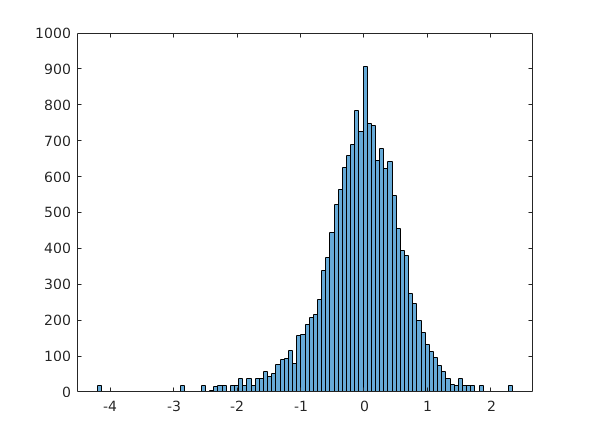

GCP_norm = quantilenorm(GCP);
histogram(quantilenorm(GCP), 100);

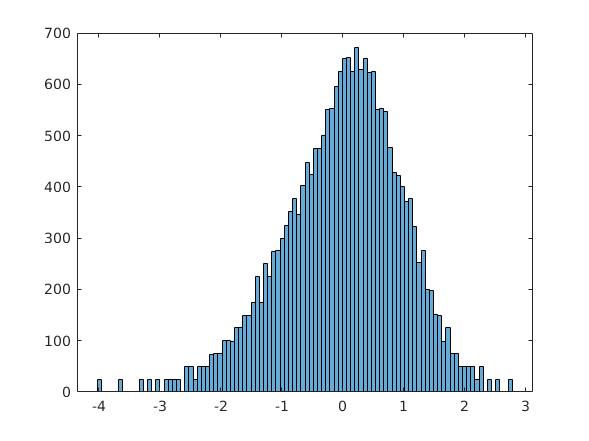

MET_norm = quantilenorm(zscore(MET));
histogram(quantilenorm(zscore(MET)), 100);

### Remove all non-finite values

We'll set all NaNs to be 0.

% Set the training size and the random number generator for the
% trainTestSplit function.
GCP_norm(isnan(GCP_norm)) = 0;
MET_norm(isnan(MET_norm)) = 0; 

### Split the dataset into a training and validation set

Let's split the data into a training and validation set. The split is 70/30.

trainingSize = 0.7;
randomState = 'default';
data = trainTestSplit(GCP_norm, MET_norm, ...
                      trainingSize, ...
                      randomState);

## Predicting metabolism from GCP with hyperparameter optimization and K-fold cross validation

Next, let's perform some hyperparameter optimzation for the LASSO models using the training set. 

% Train several regressor models to predict individual metabolites
%parpool(4);
kfold = 3;
X = data.Xtrain;
Y = data.Ytrain;

% Cross validation
for i = 1:kfold
    
    % Generate cross validation indices from the Ytrain variable.
    idx = crossvalind('Kfold', size(Y, 1), kfold);        
    
    % Create cross-validation sets
    Xtrain2 = X(idx ~= i, :);
    Ytrain2 = Y(idx ~= i, :);
    Xtest2  = X(idx == i, :);
    Ytest2  = Y(idx == i, :);
    
    % Train models + hyperparameter tuning. No internal CV is performed.
    for j = 1:size(Y, 2)
        
        tmp = fitrlinear(Xtrain2, Ytrain2(:, j), ...
                       'Learner', 'leastsquares', ...
                       'Regularization', 'lasso', ...
                       'OptimizeHyperparameters', 'auto', ...
                       'HyperparameterOptimizationOptions', ...
                         struct('AcquisitionFunctionName', ...
                                'expected-improvement-plus', ...
                                'UseParallel', true, ...
                                'Verbose', 0, ...
                                'ShowPlots', false));
                
        model.lasso_mdl{i, j}  = tmp.Beta;
        ypred2                 = predict(tmp, Xtest2);
        acc.lasso_mdl{i, j}    = corr(ypred2, Ytest2(:, j));
                
    end
end

### Select the best metabolite regressor model from K-fold cross validation

To select the best regressor model, I chose the model that had the highest Pearson correlation coefficient.

[~, lasso_idx] = max([cell2mat(acc.lasso_mdl)]);
for k = 1:size(Y, 2)
    best_mdl.lasso_mdl{k} = model.lasso_mdl{lasso_idx(k), k};
end

### Predict metabolomics values and get the validation Pearson correlation coefficient and P-value

Finally, we'll validate these LASSO models using the validation Pearson correlation coefficient and P-value from the best model. These will be reported in the [Google Sheet](https://docs.google.com/spreadsheets/d/1V0HNAR_7XCf5aWyKdpE8w8xPkBWGXnzPm0Wqer6CL7I/edit?usp=sharing).

gcp_mdls = best_mdl.lasso_mdl;
for j = 1:size(gcp_mdls, 2)
    beta = gcp_mdls{j}';
    Xtest = data.Xtest';
    ypred = beta * Xtest;
    [gcp_r(j), gcp_p(j)] = corr(ypred', data.Ytest(:, j));
    gcp_beta(:, j)       = gcp_mdls{j};
end

## Predicting GCP from metabolism with hyperparameter optimization and K-fold cross validation

Now we'll train LASSO models using metabolomics as the training set to output the histone markers.

clear data best_mdl acc;

% Set the training size and the random number generator for the
% trainTestSplit function.
data = trainTestSplit(MET_norm, GCP_norm, ...
                      trainingSize, ...
                      randomState);
kfold = 3;
X = data.Xtrain;
Y = data.Ytrain;

% Cross validation
for i = 1:kfold
    
    % Generate cross validation indices from the Ytrain variable.
    idx = crossvalind('Kfold', size(Y, 1), kfold);        
    
    % Create cross-validation sets
    Xtrain2 = X(idx ~= i, :);
    Ytrain2 = Y(idx ~= i, :);
    Xtest2  = X(idx == i, :);
    Ytest2  = Y(idx == i, :);
    
    for j = 1:size(Y, 2)
        
        tmp = fitrlinear(Xtrain2, Ytrain2(:, j), ...
                       'Learner', 'leastsquares', ...
                       'Regularization', 'lasso', ...
                       'OptimizeHyperparameters', 'auto', ...
                       'HyperparameterOptimizationOptions', ...
                         struct('AcquisitionFunctionName', ...
                                'expected-improvement-plus', ...
                                'UseParallel', true, ...
                                'Verbose', 0, ...
                                'ShowPlots', false));
                
            model.lasso_mdl{i, j}  = tmp.Beta;
            ypred2                 = predict(tmp, Xtest2);
            acc.lasso_mdl{i, j}    = corr(ypred2, Ytest2(:, j));
    end
end

### Select the best metabolite regressor model from K-fold cross validation

To select the best regressor model, I chose the model that had the highest Pearson correlation coefficient.

[~, lasso_idx] = max([cell2mat(acc.lasso_mdl)]);
for k = 1:size(Y, 2)
    best_mdl.lasso_mdl{k} = model.lasso_mdl{lasso_idx(k), k};
end

### Predict metabolomics values and get the validation Pearson correlation coefficient and P-value

Finally, we'll validate these LASSO models using the validation Pearson correlation coefficient and P-value from the best model. These will be reported in the [Google Sheet](https://docs.google.com/spreadsheets/d/1V0HNAR_7XCf5aWyKdpE8w8xPkBWGXnzPm0Wqer6CL7I/edit?usp=sharing).

%met_mdls = best_mdl.lasso_mdl;
for j = 1:size(met_mdls, 2)
    beta = met_mdls{j}';
    Xtest = data.Xtest';
    ypred = beta * Xtest;
    [met_r(j), met_p(j)] = corr(ypred', data.Ytest(:, j));
    met_beta(:, j)       = met_mdls{j};
end

## Conclusions

This notebook trains LASSO models on the CCLE metabolomics and histone marker datasets to explore the interactions between metabolism and the epigenome using statistical models. The performance of the regressors on how well they can predict metabolomics and histone marker levels is reported from these models. All results can be found in this [Google Sheet](https://docs.google.com/spreadsheets/d/1V0HNAR_7XCf5aWyKdpE8w8xPkBWGXnzPm0Wqer6CL7I/edit?usp=sharing).

Next steps involve visualizing the network, which can be found in this [Google Colab Notebook.](https://colab.research.google.com/drive/1_HWUy1uJkkF5wW1pvYePlAMeAzVoU7Mb?usp=sharing)